# Project analysis script

% 1) Load clinical table (Table S1 digitized)
% 2) Load simulated RL parameters (Table 3 based)
% 3) Match subjects (29 patients, 28 controls)
% 4) Basic stats + group comparison
% 5) Clinical–computational correlations (patients only)

clear; clc; close all;
rng(1); % reproducible random matching inside groups

% Colors (used everywhere, do not change aesthetics)
ctrlC = [0.55 0.55 0.60]; % Controls
patC = [0.27 0.45 0.90]; % Patients
ctrlB = [0.82 0.74 0.55]; % Controls(reward)
patB = [0.93 0.40 0.20]; % Patients (reward)

## 1. Load clinical data

clinFile = 'Composition of the sample.csv';
Tclin = readtable(clinFile);

% Expected columns (case-sensitive, check & fix if needed):
% ID, Group, Sex, Age, Diagnosis, BPI_severity, McGill, ...
% Pain_diary, Facit, Fatigue_diary, BDI, GAD, Medication

% Some columns may be read as cell from Excel, convert to double
numVars = {'BPI_severity','McGill','Pain_diary','Facit', ...
           'Fatigue_diary','BDI','GAD'};
for i = 1:numel(numVars)
    v = Tclin.(numVars{i});
    if iscell(v)
        Tclin.(numVars{i}) = cellfun(@str2double, v);
    end
end

% Keep the 57 rows that have real numeric data (avoid empty lines)
Tclin = Tclin(~all(ismissing(Tclin(:,numVars)),2), :);

## 2. Load simulated RL parameters

paramFile = 'sim_parameters_mapped_to_real_IDs.csv';
Tpar = readtable(paramFile);

% Expected columns: ID, Group, betaR, betaP, alpha, decay, lapse

% Check that group counts match the clinical table
nPain_clin  = sum(strcmp(Tclin.Group,  'Patient'));
nCtrl_clin  = sum(strcmp(Tclin.Group,  'Control'));
nPain_par   = sum(strcmp(Tpar.Group,   'Patient'));
nCtrl_par   = sum(strcmp(Tpar.Group,   'Control'));

fprintf('Clinical: %d patients, %d controls\n', nPain_clin, nCtrl_clin);

Clinical: 29 patients, 28 controls


fprintf('Params  : %d patients, %d controls\n\n', nPain_par, nCtrl_par);

Params  : 29 patients, 28 controls



## 3. Randomly match parameters to clinical subjects within group

% Split clinical table by group
clinPain = Tclin(strcmp(Tclin.Group,'Patient'), :);
clinCtrl = Tclin(strcmp(Tclin.Group,'Control'), :);

parPain  = Tpar(strcmp(Tpar.Group,'Patient'), :);
parCtrl  = Tpar(strcmp(Tpar.Group,'Control'), :);

% Randomly permute parameter rows, then assign in order
permPain = randperm(height(parPain));
permCtrl = randperm(height(parCtrl));

parPain  = parPain(permPain, :);
parCtrl  = parCtrl(permCtrl, :);

% Attach parameter columns to clinical tables
clinPain.betaR = parPain.betaR;
clinPain.betaP = parPain.betaP;
clinPain.alpha = parPain.alpha;
clinPain.decay = parPain.decay;
clinPain.lapse = parPain.lapse;

clinCtrl.betaR = parCtrl.betaR;
clinCtrl.betaP = parCtrl.betaP;
clinCtrl.alpha = parCtrl.alpha;
clinCtrl.decay = parCtrl.decay;
clinCtrl.lapse = parCtrl.lapse;

% Merge back together
T = [clinPain; clinCtrl];

% Optional: sort by group and ID
T = sortrows(T, {'Group','ID'});

writetable(T, 'Combined_clinical_RL_57subjects.csv');

## 4. Group-level summary stats and t-tests

isPain = strcmp(T.Group,'Patient');
isCtrl = strcmp(T.Group,'Control');

params = {'betaR','betaP','alpha','decay','lapse'};

fprintf('=== Group means (mean ± SD) ===\n');

=== Group means (mean ± SD) ===


for i = 1:numel(params)
    v = T.(params{i});
    mPain = mean(v(isPain),'omitnan');
    sPain = std(v(isPain),'omitnan');
    mCtrl = mean(v(isCtrl),'omitnan');
    sCtrl = std(v(isCtrl),'omitnan');
    fprintf('%-6s  Pain: %6.3f ± %5.3f   Ctrl: %6.3f ± %5.3f\n', ...
        params{i}, mPain, sPain, mCtrl, sCtrl);
end

betaR   Pain: 12.306 ± 5.451   Ctrl:  8.294 ± 5.028
betaP   Pain: 10.329 ± 2.993   Ctrl:  6.573 ± 4.930
alpha   Pain:  0.563 ± 0.296   Ctrl:  0.582 ± 0.192
decay   Pain:  0.091 ± 0.110   Ctrl:  0.018 ± 0.023
lapse   Pain:  0.098 ± 0.032   Ctrl:  0.027 ± 0.002


fprintf('\n=== Two-sample t-tests (Pain vs Control) ===\n');


=== Two-sample t-tests (Pain vs Control) ===



for i = 1:numel(params)
    vPain = T.(params{i})(isPain);
    vCtrl = T.(params{i})(isCtrl);
    [~,p,~,stats] = ttest2(vPain, vCtrl);
    fprintf('%-6s  t(%d) = %5.3f, p = %.4f\n', ...
        params{i}, stats.df, stats.tstat, p);
end

betaR   t(55) = 2.885, p = 0.0056
betaP   t(55) = 3.491, p = 0.0010
alpha   t(55) = -0.280, p = 0.7807
decay   t(55) = 3.427, p = 0.0012
lapse   t(55) = 11.689, p = 0.0000


fprintf('\n');

## 5. Correlations within patients (clinical vs RL parameters)

% Focus on punishment sensitivity betaP
painVars = {'BPI_severity','McGill','Pain_diary', ...
            'Facit','Fatigue_diary','BDI','GAD'};

fprintf('=== Correlations in Patient group: betaP vs clinical ===\n');

=== Correlations in Patient group: betaP vs clinical ===


for i = 1:numel(painVars)
    x = clinPain.(painVars{i});
    y = clinPain.betaP;
    valid = ~(isnan(x) | isnan(y));
    if sum(valid) < 5
        fprintf('%-14s  not enough data\n', painVars{i});
        continue;
    end
    [R,p] = corr(x(valid), y(valid), 'Type','Pearson');
    fprintf('%-14s  r = %5.3f, p = %.4f, n = %d\n', ...
        painVars{i}, R, p, sum(valid));
end

BPI_severity    r = -0.005, p = 0.9793, n = 29
McGill          r = -0.019, p = 0.9215, n = 29
Pain_diary      r = 0.115, p = 0.5536, n = 29
Facit           r = -0.157, p = 0.4158, n = 29
Fatigue_diary   r = 0.300, p = 0.1134, n = 29
BDI             r = 0.206, p = 0.2927, n = 28
GAD             r = 0.045, p = 0.8196, n = 28


fprintf('\n');

## 6. Figures

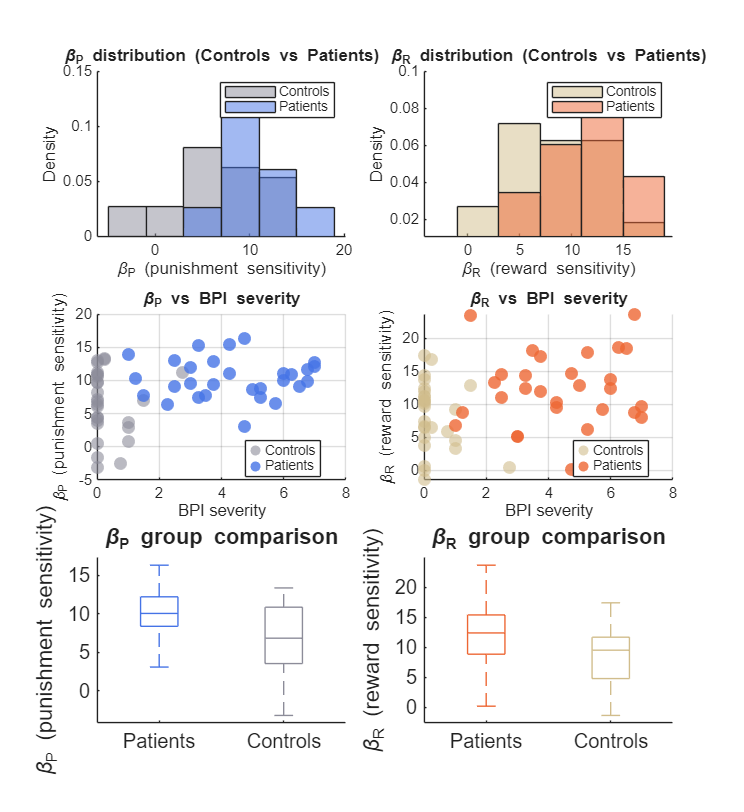

figure;
set(gcf,'Position',[200 200 1100 1200]);

% Data
betaP_pat  = Tpar.betaP(Tpar.Group=="Patient");
betaP_ctrl = Tpar.betaP(Tpar.Group=="Control");
betaR_pat  = Tpar.betaR(Tpar.Group=="Patient");
betaR_ctrl = Tpar.betaR(Tpar.Group=="Control");

% (1,1) Distribution βP
subplot(3,2,1); hold on;

edgesP = -5:4:20;   % unified bin edges for βP

histogram(betaP_ctrl, edgesP, ...
    'Normalization','pdf','FaceAlpha',0.5,'FaceColor',ctrlC);

histogram(betaP_pat, edgesP, ...
    'Normalization','pdf','FaceAlpha',0.5,'FaceColor',patC);

xlabel('\beta_P (punishment sensitivity)');
ylabel('Density');
title('\beta_P distribution (Controls vs Patients)');
legend({'Controls','Patients'});
box off;


% (1,2) Distribution βR
subplot(3,2,2); hold on;

edgesR = -5:4:20;   % unified bin edges for βR

histogram(betaR_ctrl, edgesR, ...
    'Normalization','pdf','FaceAlpha',0.5,'FaceColor',ctrlB);

histogram(betaR_pat, edgesR, ...
    'Normalization','pdf','FaceAlpha',0.5,'FaceColor',patB);

xlabel('\beta_R (reward sensitivity)');
ylabel('Density');
title('\beta_R distribution (Controls vs Patients)');
legend({'Controls','Patients'});
box off;


% (2,1) βP vs BPI severity scatter
subplot(3,2,3); hold on;

scatter(clinCtrl.BPI_severity, clinCtrl.betaP, 60, 'o', ...
        'MarkerFaceColor',ctrlC, 'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.6);

scatter(clinPain.BPI_severity, clinPain.betaP, 60, 'o', ...
        'MarkerFaceColor',patC, 'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.8);

xlabel('BPI severity');
ylabel('\beta_P (punishment sensitivity)');
title('\beta_P vs BPI severity');
legend({'Controls','Patients'}, 'Location','best');
grid on; box off;

% (2,2) βR vs BPI severity scatter
subplot(3,2,4); hold on;

scatter(clinCtrl.BPI_severity, clinCtrl.betaR, 60, 'o', ...
        'MarkerFaceColor',ctrlB, 'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.6);

scatter(clinPain.BPI_severity, clinPain.betaR, 60, 'o', ...
        'MarkerFaceColor',patB, 'MarkerEdgeColor','none', 'MarkerFaceAlpha',0.8);

xlabel('BPI severity');
ylabel('\beta_R (reward sensitivity)');
title('\beta_R vs BPI severity');
legend({'Controls','Patients'}, 'Location','best');
grid on; box off;

% (3,1) βP group boxplot
subplot(3,2,5);

dataP   = [betaP_pat; betaP_ctrl];
groupP  = [repmat("Patients",length(betaP_pat),1);
           repmat("Controls",length(betaP_ctrl),1)];

boxplot(dataP, groupP, 'Colors',[patC; ctrlC], 'Symbol','');
ylabel('\beta_P (punishment sensitivity)');
title('\beta_P group comparison');
set(gca,'FontSize',12,'FontName','Arial','Box','off');

% (3,2) βR group boxplot

subplot(3,2,6);

dataR   = [betaR_pat; betaR_ctrl];
groupR  = [repmat("Patients",length(betaR_pat),1);
           repmat("Controls",length(betaR_ctrl),1)];

boxplot(dataR, groupR, 'Colors',[patB; ctrlB], 'Symbol','');
ylabel('\beta_R (reward sensitivity)');
title('\beta_R group comparison');
set(gca,'FontSize',12,'FontName','Arial','Box','off');